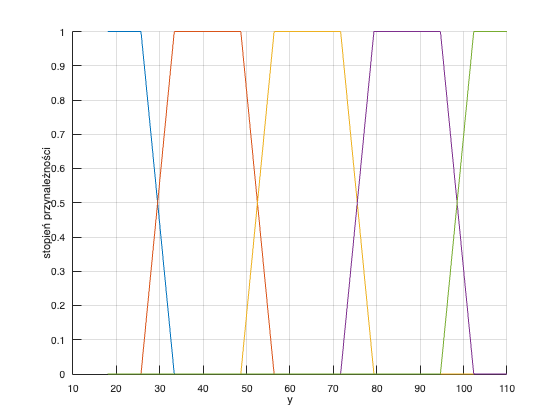

clear all;
% trapez
% 
% 
% Parametry testowe
N = 5; % Liczba funkcji przynależności
[mf_h1, mf_h2] = generate_trapezoidal_mf_functions(N); % Wywołanie istniejącej funkcji


% Zakresy dla zmiennych h2 i h1
h2_pp_min = 18;
h2_pp_max = 110;
h1_pp_min = mf_h1(1).params(1); % Początek zakresu h1
h1_pp_max = mf_h1(end).params(4); % Koniec zakresu h1

% Dyskretyzacja zakresów dla wykresu
h2_range = linspace(h2_pp_min, h2_pp_max, 1000);
h1_range = linspace(h1_pp_min, h1_pp_max, 1000);

% Wyświetlanie funkcji przynależności dla h2
figure;
hold on;
grid on;
% title('Trapezoidalne funkcje przynależności dla h2');
xlabel('y');
ylabel('stopień przynależności');
for i = 1:N
    % Obliczanie wartości przynależności
    mf_values_h2 = evalmf( mf_h2(i),h2_range);
    plot(h2_range, mf_values_h2, 'DisplayName', sprintf('MF h2 #%d', i));
end
% legend show;
exportgraphics(gcf,fullfile('wykresy', 'zad2_fun_trapezoidalna.png'));

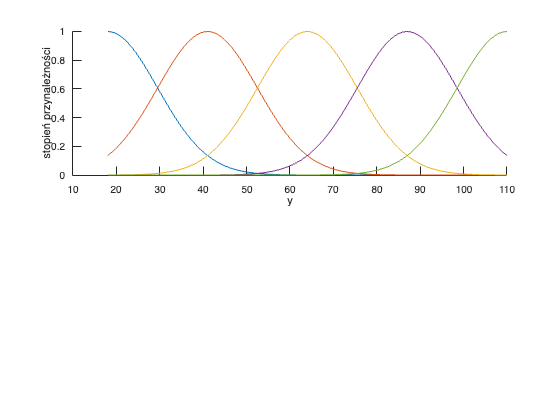

% Gaus
% 
% 
clear;
% Parametry testowe
N = 5; % liczba funkcji przynależności

% Generowanie funkcji przynależności
[mf_h1, mf_h2] = generate_gaussian_mf_functions(N);

% Zakresy dla wykresów
h2_pp_min = 18;
h2_pp_max = 110;

% Tworzenie punktów do oceny funkcji przynależności
h2_values = linspace(h2_pp_min, h2_pp_max, 100);
h1 = @(h2) h2 * (12 / 13)^2; % Funkcja przekształcająca h2 na h1
h1_values = h1(h2_values);

% Wykresy funkcji przynależności
figure;

% Wykres dla h2
subplot(2, 1, 1);
hold on;
for i = 1:N
    plot(h2_values, evalmf( mf_h2(i),h2_values));
end
hold off;
% title('Funkcje przynależności dla h2');
xlabel('y');
ylabel('stopień przynależności');
% legend;
exportgraphics(gcf,fullfile('wykresy', 'zad2_fun_gauss.png'));

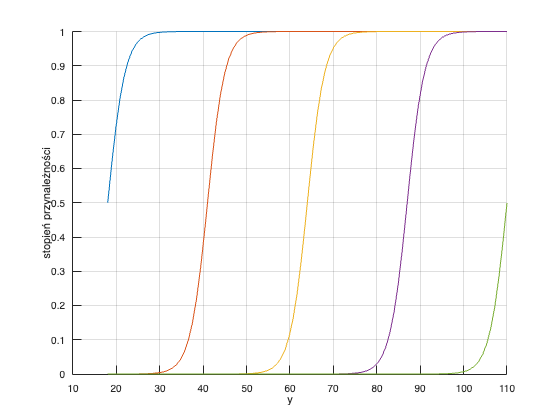

%Sigmodalna

clear all;
% Skrypt do testowania funkcji generate_sigmoid_mf_functions

% Liczba funkcji przynależności do wygenerowania
N = 5;

% Wywołanie funkcji generującej funkcje przynależności
[mf_h1, mf_h2] = generate_sigmoid_mf_functions(N);

% Przygotowanie wektora wartości, na którym będziemy testować funkcje przynależności
h2_values = linspace(18, 110, 100);  % Wartości h2 od 18 do 110
h1_values = arrayfun(@(h2) h2 * (12 / 13)^2, h2_values);  % Obliczanie odpowiadających h1 dla h2

% Rysowanie funkcji przynależności h2
figure;
hold on;
xlabel('y');
ylabel('stopień przynależności');
grid on;
for i = 1:N
    % Obliczanie wartości funkcji sigmoidalnej dla h2
    h2_mf_values = arrayfun(@(h2) evalmf(mf_h2(i), h2), h2_values);
    plot(h2_values, h2_mf_values);
end
exportgraphics(gcf,fullfile('wykresy', 'zad2_fun_sigmoidalna.png'));
hold off;